## Part A: Univariate statistics

Already in this series of practical's, we have been using univariate statistics. These are descriptive statistics which summarise and describe datasets. These are often the first things that you will assess once you have cleaned and organised your data. They help to provide a general characterisation of the information that is present. You will no doubt have come across many of these previously. However, here we will explore how to extract some key summary statistics from within the MATLAB environment.

We will run through this using some example data obtained from two sediment cores:

clear all; close all; clc;

Define the working folder that you are using

folderIn = 'C:\Users\Matt\OneDrive - Newcastle University\Teaching\2021 - 22\GEO8026\Lecture 4\';

Download example data from gitHub and save it within `folderIn` as `example1.xlsx`

websave([folderIn 'core_data.xlsx'] , 'https://github.com/CatchmentSci/GEO8026_21_22/blob/main/Practical%204/data/example_core_data.xlsx?raw=true'); % Download data

Read the data into MATLAB. Note that two seperate lists of characters can be joined into one through the use of square brackets:  

C = readtable([folderIn 'core_data.xlsx']); 

The data that we have just loaded is a 325x2 array consisting of independent data (:,1), and response/dependant variable (:,2). Let's extract this data into two seperate variables:

d = C{:,2:3}; % Extract the second and third column (shear stress 1 and 2)

**Sample size: **The number of observations that you have is important as it strongly determines the power of the statistical tests that you conduct. There are few hard rules when it comes to minimum sample size for statistical tests although some tests do have a lower limit of ~30. If we have variable containing our observations, we can easily determine the number of samples in each column using:

sample_num = length(d)

sample_num = 35

If we have a `nxm` variable where the samples are placed in multiple rows and colums (e.g. in prep for ANOVA analysis) and we want to determine the total number of samples, we can do so by:

sample_num = numel(d)

sample_num = 70

This command counts up the total number of elements within the array. Conversely, if we wanted to know the length of a particular column, or row we could use the following commands:

sample_num = length(d(:,1)) % extracts the length of the first column

sample_num = 35

sample_num = length(d(1,:)) % extracts the length of the first row

sample_num = 2

If however, we have data within our variable which is `NaN`, and we want to exclude this from the count, we can modify the commands accordingly:

idx = find(~isnan(d(:,1)) == 1); % find only those that ~NaN
sample_num = idx;

idx = find(~isnan(d) == 1); % find only those that ~NaN
sample_num = length(idx);

idx = find(~isnan(d(1,:) == 1)); % find only those that ~NaN
sample_num = length(idx) % extracts the length of the first row

sample_num = 2

**Measures of central tendency: **These descriptors tell us the typical average value about which the samples are distributed. These are all called in much the same way. The analysis is conduced down each column. So if you have an array which is 35 elements long (rows) and 2 elements wide (columns), you would obtain 2 outputs (one for each column).

central_t = mean(d) % arithmetic mean

central_t =    10.2114   28.1857


central_t = mode(d) % modal value

central_t =     10    10


central_t = median(d) % median value

central_t =     10    22


However, if you wanted to obtain the results for the entire array, you could do this by combining all of the columns together. This can be done using the colon operator:

central_t = mean(d(:)) % arithmetic mean

central_t = 19.1986

central_t = mode(d(:)) % modal value

central_t = 10

central_t = median(d(:)) % median value

central_t = 13

Each of these commands will treat zeros as a zero value (not a missing number), and `NaN` values will result in an output of `NaN`. Therefore, we have to ensure we only select those values of interest i.e. `~NaN`. We can again do this by filtering these from the call using indexing (as above), or use the inbuilt functionality of MATLAB:

central_t = mean(d,'omitnan') % arithmetic mean

central_t =    10.2114   28.1857


central_t = mode(d) % modal value command automatically omits NaNs

central_t =     10    10


central_t = median(d,'omitnan') % median value

central_t =     10    22


We can also specify which particular column we would like to analyse. For example, if we wanted to only analyse the first colum we could write:

central_t = mean(d(:,1),'omitnan') % arithmetic mean

central_t = 10.2114

central_t = mode(d(:,1)) % modal value

central_t = 10

central_t = median(d(:,1),'omitnan') % median value

central_t = 10

Similarly, we can analyse along the rows rather than the colums if we specify the dimension of analysis. In the case above where we have a `35x2 array`, running the commands below would provide 35 outputs with the average being calculated for each row. This can be used in conjunction with the `omitnan` flag also.

central_t = mean(d,2) % arithmetic mean

central_t =     2.5000
    3.5000
    4.5000
    5.0000
    6.0000
    7.8000
   10.0000
   10.0000
   11.5000
   12.0000


central_t = mode(d,2) % modal value

central_t =     2.0000
    2.0000
    3.0000
    3.0000
    4.0000
    5.6000
   10.0000
   10.0000
   10.0000
   10.0000


central_t = median(d,2) % median value

central_t =     2.5000
    3.5000
    4.5000
    5.0000
    6.0000
    7.8000
   10.0000
   10.0000
   11.5000
   12.0000


**Scale: **Measures the distribution of the samples around the central location. This can be useful for providing summary information describing the distribution of the data. We will explore the common approaches for this here using the variable `[d]` as our target. Remeber this consists of two columns, so two outputs would be expected for each. Firstly, we have the range. This statistic summarises the difference between the maximum and minimum values of sample data. However, an alternative way of presenting this would be to explicitly provide the miniumum and maximum values of the variable:

% Each of the outputs in individual variables
d_range     = range(d) % range

d_range =     17   148


d_min       = min(d) % min

d_min =      3     2


d_max       = max(d) % max

d_max =     20   150


d_summary   = [range(d); min(d); max(d)] % combine the stastics in one variable

d_summary =     17   148
     3     2
    20   150


As default this is calculated for each colum of the array. However, as with all of these methods, you can specify the particular column, or specify an alernate dimension (e.g. along rows).

The min, max, and range are quantifications of the extremes of the dataset. However, we may be more interested in the distibution of a particular subset of the data. For example, if we have a few extremely low and extremely high values we may want to exclude these when we present information about the distribution. In these instances, we may choose to provide information about a particular percentile of the data. One example of this is the interquartle range which is the range of the middle 50% of the data when ranked. However, we can also specify the percentle of interest. Let's explore this:

Y   = iqr(d); % interquartile range
Y   = prctile(d,1) % 1st percentile i.e. lower 1%

Y =      3     2


Y   = prctile(d,99) % 99th percentile i.e. upper 1%

Y =     20   150


Other ways of describing the sample distribution are refered to as being moments about the mean. The second moment is the sample variance : $\sigma^2 = \frac{\displaystyle\sum_{i=1}^{n}(x_i - \mu)^2} {n}$ and the standard deviation is derived from this:$\sigma= \sqrt{\sigma^2 }$. These can be extracted by:

var_d   = var(d); % variance
std_d   = sqrt(var_d) % sqrt of variance equals std%

std_d =     3.6993   28.9856


std_d   = std(d) % or call it independently

std_d =     3.6993   28.9856


**Shape:  **The third and fourth moment about the mean tell us about the shape of the sample distribution. These are the skewness $\mu_3$ , and kurtosis $\mu_4$:

$\mu_3 = \frac{\displaystyle\sum_{i=1}^{n}(x_i - \mu)^3} {\sigma^3}$ Skewness describes the asymetry of the distribution. Negative indicates spread to the right and positive to the left

$\mu_4 = \frac{\displaystyle\sum_{i=1}^{n}(x_i - \mu)^4} {\sigma^4}$ Kurtosis describes the flatness of the distribution. A value > 1 can indicate a peaked distribution whereas < 1 a flat distribution. These can be extracted by:

skew_d   = skewness(d); % skewness
kurt_d   = kurtosis(d) % kurtosis

kurt_d =     2.9233   10.2409


## Part B: Hypothesis testing

Now we understand a little about our data we may wish to delve deeper. Whilst we can compare the values of the above statistics with those from a different population and calculate whether there is a difference (in an absolte sense), we don't necessarily know whether this difference is due to chance, or whether the differences are actually statistically significant. Thankfully, there are a range of standard methods for testing for differences and similarities between a set of samples and either a known value/distribution (one-sample tests) or a second set of samples (two-sample tests). Formalising and testing of a hypothesis are key to this process (see lecture notes). Here we will show how to extract a range of statistics (described in the lecture notes) from the MATLAB environment. 

**Testing for normality: **Many statistical tests operate under the assumption that the data are normally distributed.This is because they are seeking to test the mean of the distribution, which is influenced by outliers. We can test this assumption by calling one of two tests, namely the Anderson-Darling test, or Lilliefors test. Both are valid for testing whether the distribution is normally distributed. The null hypothesis is that the data comes from a normal distribution:

[h,p,adstat,cv] = adtest(d(:,1)) % only assess the first column

h = logical
   0


p = 0.5543

adstat = 0.3131

cv = 0.7346

if p > 0.05
    disp 'Unable to reject the null hypotesis that the data comes from a normal distribution '
end

Unable to reject the null hypotesis that the data comes from a normal distribution 


% h = test outcome 0 = cannot reject null hypothesis
% p = p value
% adstst = Test statistic for the Anderson-Darling test
% cv = critical value that adstat is compared with

[h,p,kstat,critval] = lillietest(d(:,1))

h = 0

p = 0.5000

kstat = 0.0957

critval = 0.1476

if p > 0.05
    disp 'Unable to reject the null hypotesis that the data comes from a normal distribution '
end

Unable to reject the null hypotesis that the data comes from a normal distribution 


% h = test outcome 0 = cannot reject null hypothesis
% p = p value
% kstat = Test statistic for the Lilliefors test
% cv = critical value that kstat is compared with

**One-sample tests:** One sample tests are used to test whether a particular sample could have been drawn from a population with known parameters. The tests compare an observed sample statistic with a given population parameter. 

[h,p,ci,stats] = ttest(d(:,1),10) % T-test to see whether the data in the vector x comes from a normal distribution with mean of 10 

h = 0

p = 0.7373

ci =     8.9407
   11.4822


stats = struct with fields:
    tstat: 0.3381
       df: 34
       sd: 3.6993


if p > 0.05
    disp 'Unable to reject the null hypotesis that the data in x comes from a normal distribution with mean equal to 10'
end

Unable to reject the null hypotesis that the data in x comes from a normal distribution with mean equal to 10


% h = test outcome. 0 = cannot reject null hypothesis
% p = p value
% ci = Confidence interval for the true population mean (default is at the 95% level)
% stats = full stats output - see MATLAB documentation (doc ttest)


[h,p,ci,zval] = ztest(d(:,1),10,2) % Z-test to see whether the data in the vector x comes from a normal distribution with mean of 10 and standard deviation of 2 

h = 0

p = 0.5317

ci =     9.5488
   10.8740


zval = 0.6254

if p > 0.05
    disp 'Unable to reject the null hypotesis that the data in x comes from a normal distribution with mean equal to 10 and std of 2'
end

Unable to reject the null hypotesis that the data in x comes from a normal distribution with mean equal to 10 and std of 2


% h = test outcome. 0 = cannot reject null hypothesis
% p = p value
% ci = Confidence interval for the true population mean (default is at the 95% level)
% z-value = Test statistic.

fit_dist        = fitdist(d(:,1),'Weibull'); % test decision for the null hypothesis that the data in the vectors x come from a population with a defined distribution. In the above case, a Weibull distribution. 
[h,p,stats]     = chi2gof(d(:,1),'CDF',fit_dist);
if p > 0.05
    disp 'Unable to reject the null hypotesis that the data in the vector x comes from a population with the defined distribution'
end

Unable to reject the null hypotesis that the data in the vector x comes from a population with the defined distribution


% h = test outcome. 0 = cannot reject null hypothesis
% p = p value
% stats = full stats output - see MATLAB documentation (doc chi2gof)


**Two-sample tests:** Two sample tests are used to test whether two sets of data could have come from the same population. We will first start with parametric tests. An assumption of this type of test is that the data comes from a normal (or approximately normal) distribution. 

[h,p,ci,stats] = ttest(d(:,1),d(:,2)) % tests the null hypothesis that the pairwise difference between data vectors x and y has a mean equal to zero

h = 1

p = 3.4073e-04

ci =   -27.1471
   -8.8015


stats = struct with fields:
    tstat: -3.9822
       df: 34
       sd: 26.7029


if p > 0.05
    disp 'Unable to reject the null hypotesis that the pairwise difference between data vectors x and y has a mean equal to zero';
else
    disp 'The null hypotesis that the pairwise difference between data vectors x and y has a mean equal to zero is rejected';
end

The null hypotesis that the pairwise difference between data vectors x and y has a mean equal to zero is rejected


% h = test outcome. 0 = cannot reject null hypothesis
% p = p value
% ci = Confidence interval for the true population mean (default is at the 95% level)
% stats = full stats output - see MATLAB documentation (doc ttest)

[h,p,ci,stats] = vartest2(d(:,1),d(:,2)) % tests the null hypothesis that the data in the vectors x and y come from a normal distribution with the same variance

h = 1

p = 5.5532e-22

ci =     0.0082
    0.0323


stats = struct with fields:
    fstat: 0.0163
      df1: 34
      df2: 34


if p > 0.05
    disp 'Unable to reject the null hypotesis that the data in the vectors x and y come from a normal distribution with the same variance';
else
    disp 'The null hypotesis that the data in the vectors x and y come from a normal distribution with the same variance is rejected';
end

The null hypotesis that the data in the vectors x and y come from a normal distribution with the same variance is rejected


We can also perform non-parametric, two-sample tests which do not assume normality.

[p,h,stats]     = ranksum(d(:,1),d(:,2)) % tests the null hypothesis that data in x and y are samples from continuous distributions with equal medians

p = 3.3031e-05

h = logical
   1


stats = struct with fields:
       zval: -4.1515
    ranksum: 889


if p > 0.05
    disp 'Unable to reject the null hypothesis that data in x and y are samples from continuous distributions with equal medians';
else
    disp 'The null hypothesis that data in x and y are samples from continuous distributions with equal medians is rejected';
end

The null hypothesis that data in x and y are samples from continuous distributions with equal medians is rejected


% p = p value
% h = test outcome. 0 = cannot reject null hypothesis
% stats = full stats output - see MATLAB documentation (doc ranksum)


[h,p,stats] = ansaribradley(d(:,1),d(:,2));
if p > 0.05
    disp 'Unable to reject the null hypothesis that the data in vectors x and y comes from the same distribution';
else
    disp 'The null hypothesis that the data in vectors x and y comes from the same distribution is rejected';
end

The null hypothesis that the data in vectors x and y comes from the same distribution is rejected


% p = p value
% h = test outcome. 0 = cannot reject null hypothesis
% stats = full stats output - see MATLAB documentation (doc ansaribradley)


**n-sample tests:** When more than two samples need to be tested, rather than using multiples of a two-sample test it is better to use an integrated multiple testing approach such as ANOVA. 

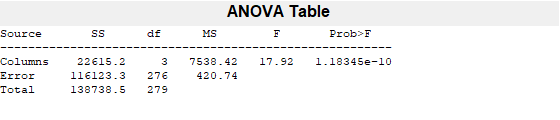

d = repmat(d,2); % duplicate d so that is now a nx4 array where columns 3 and 4 are replicates of 1 and 2
[p,tbl,stats] = anova1(d); % where x is a 2D array where columns represent different sample types/conditions

if p > 0.05
    disp 'Unable to reject the null hypothesis that all samples stored in variable x are drawn from populations with the same mean';
else
    disp 'The null hypothesis that all samples stored in variable x are drawn from populations with the same mean is rejected';
end

The null hypothesis that all samples stored in variable x are drawn from populations with the same mean is rejected


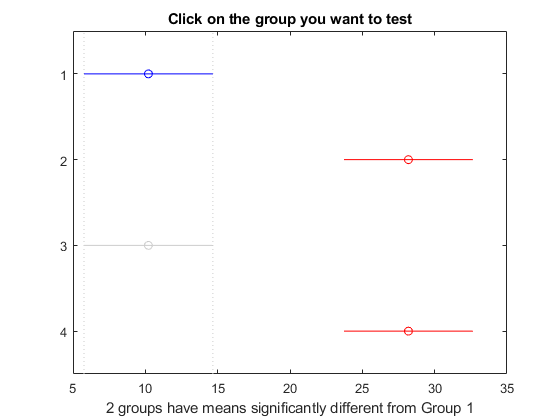

% p = p value: if less than the sig level (e.g. 0.05) then at least one group mean is different
% tbl = full anova table -  see MATLAB documentation (doc anova1)
% stats = full stats output - used for the multi comparison tests

multcompare(stats); % provides an interactive way of assessing which groups have means that are significantly different from other groups

## Part C: Regression 

When doing any kind of regression analysis we need to consider what the relationship between the independent and dependent variables is expected to be. Too often, people produce a linear fit between two variables that do not follow a linear response. If the expected relationship is non-linear, then you should consider a non-linear function or transformation of the xData, yData, or both. Whilst this is often possible to achieve using a high order polynomial, interpretation of the coefficients may be more troublesoome than transformation of the data. Let's work through some examples here:

First, lets try to find a solution for variables where the `yObs` values increase rapidly to small changes in `xObs` when `xObs` is small, and then the rate of change slows dramatically as the value of `xObs` increases. In this situation, a linear fit can be achieved by performing a `log10(x)`. This produces what is known as a linear-log model. Work through the script by using breakpoints and stepping each line to understand how the code is executed:

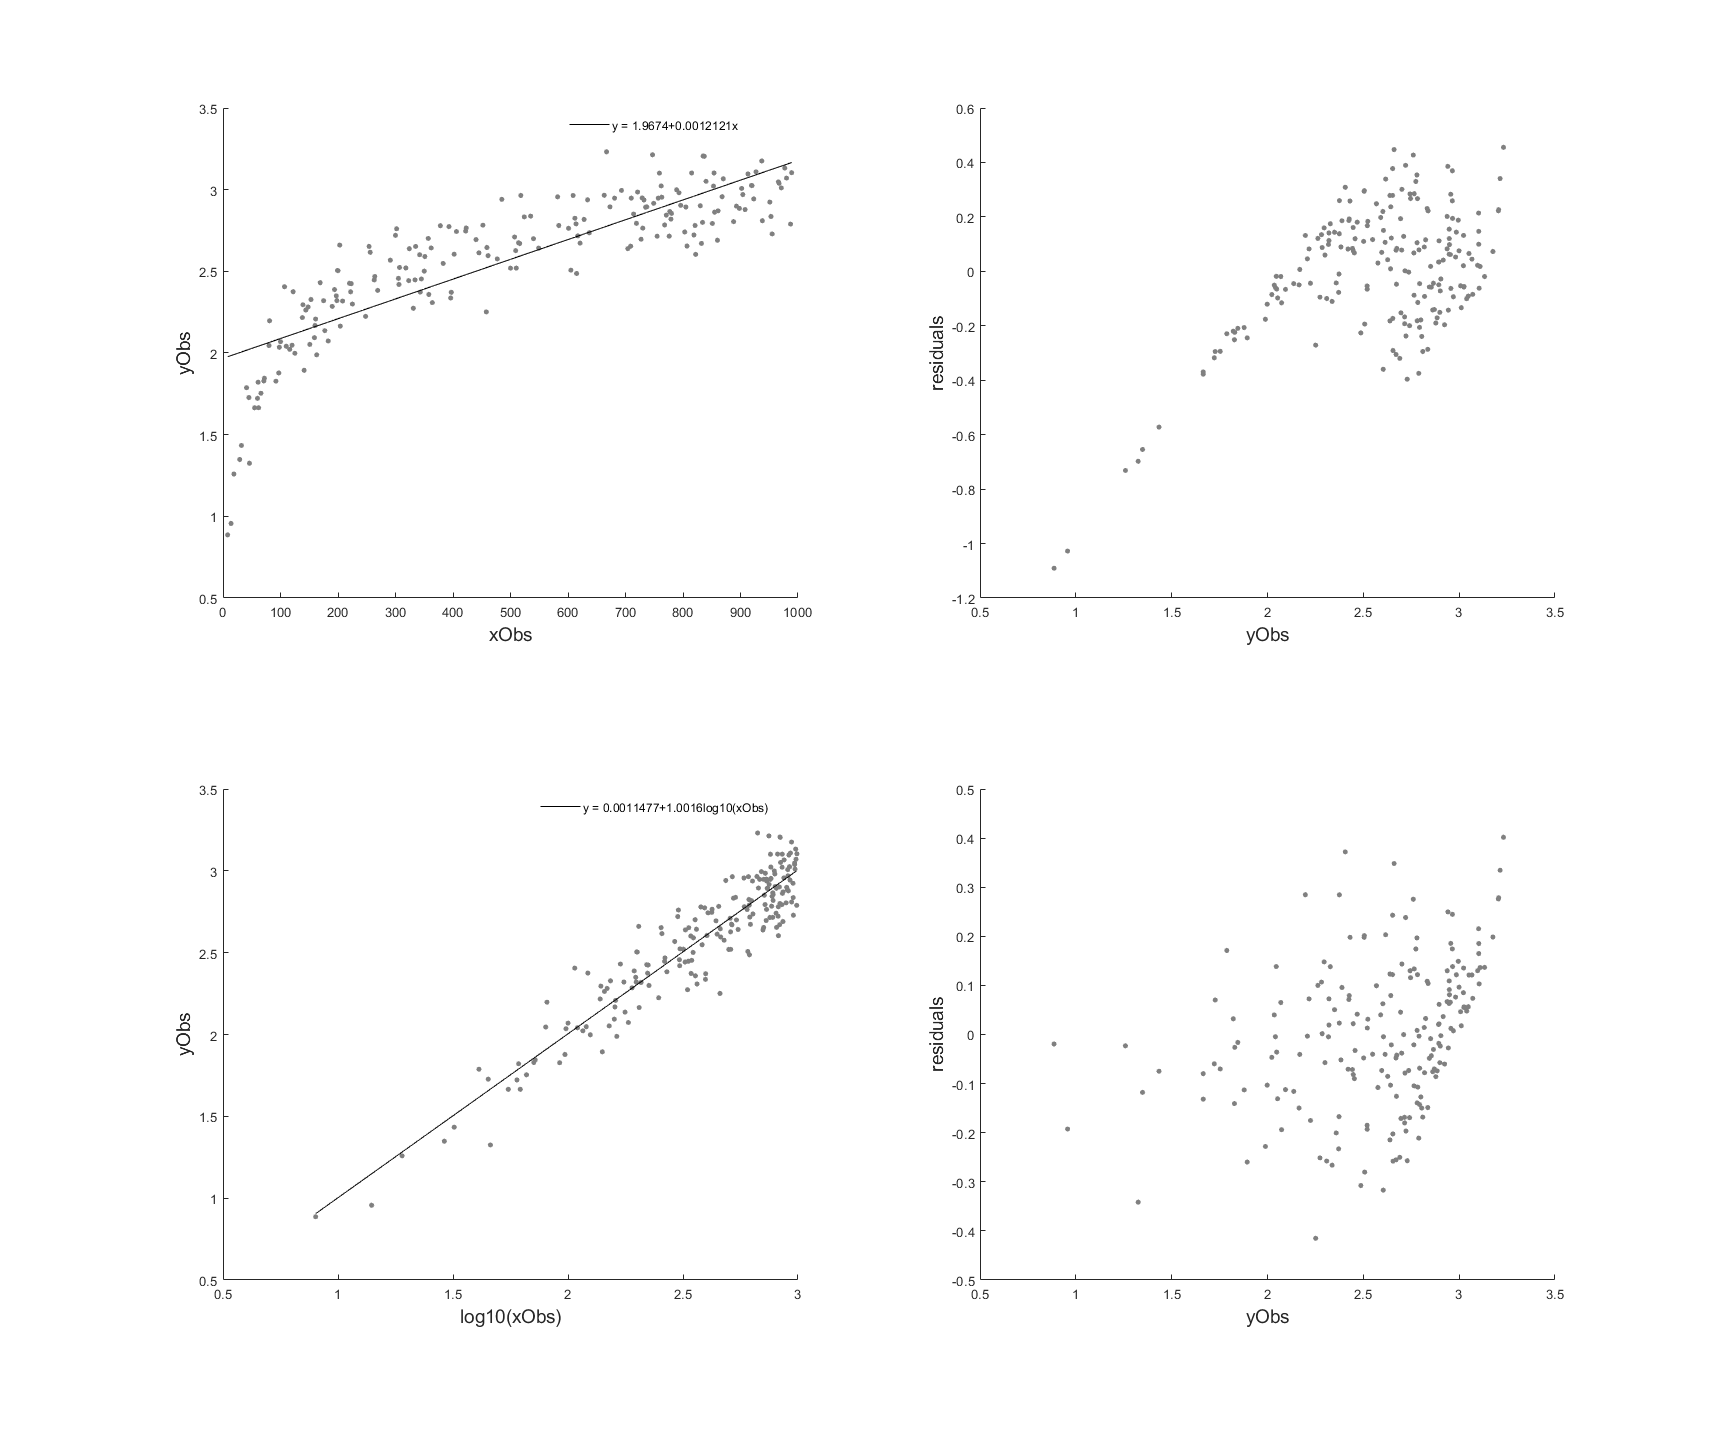

run('log10_transform_example.m');

close all;

Next we do the same with data where `yObs` increase rapidly to small changes in `xObs` when `xObs` is small, and then the rate of change slows slightly as the value of `xObs` increases. In this situation, a linear fit can be achieved by performing a `sqrt(x)`. Work through the script by using breakpoints and stepping each line to understand how the code is executed:

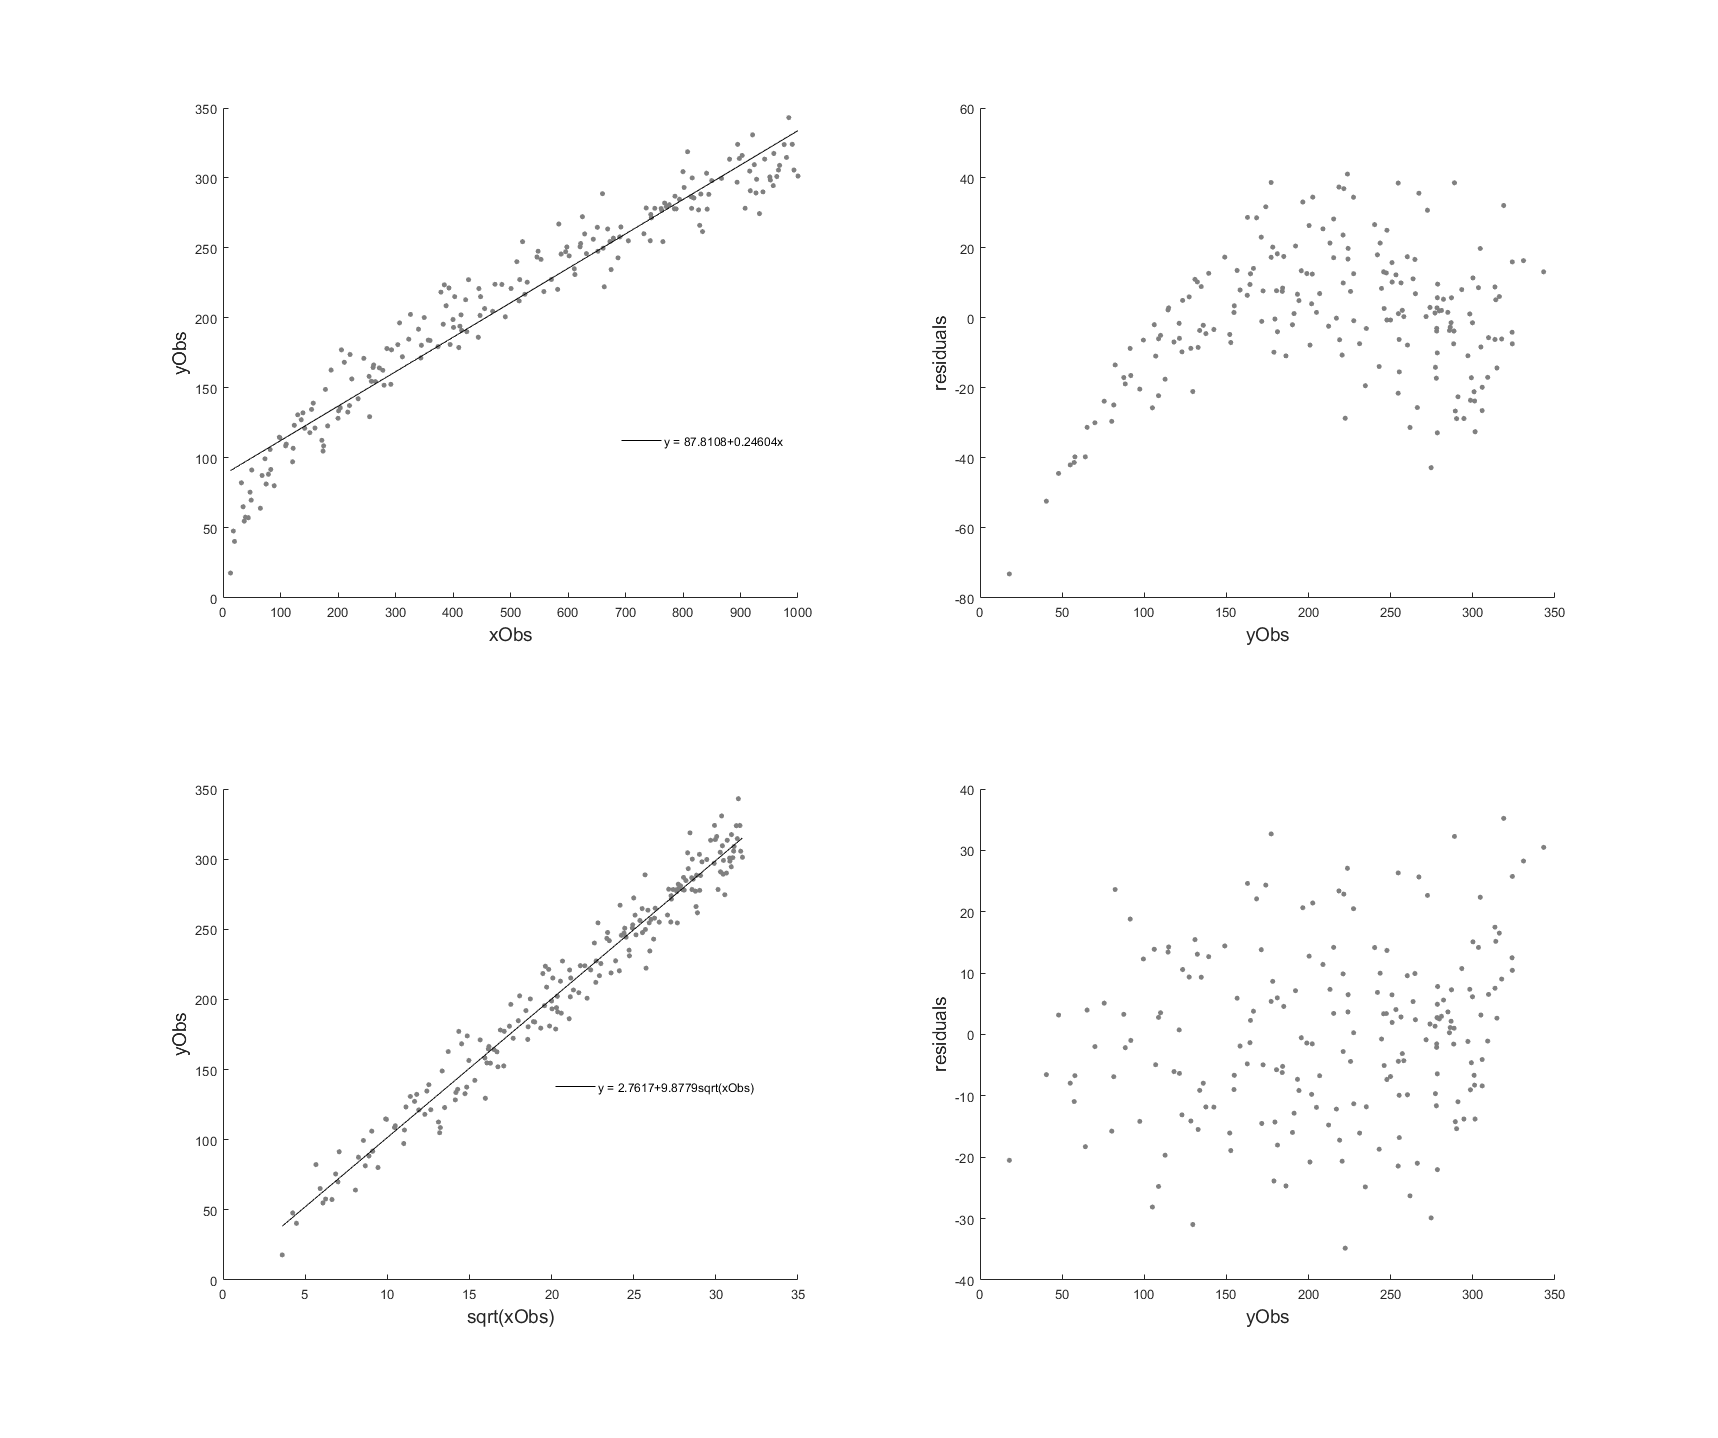

run('sqrt_transform_example.m');

close all;

Next we do the same with data where `yObs` increase slowly to changes in `xObs` when `xObs` is small, and then the rate of change increases as the value of `xObs` increases. In this situation, a linear fit can be achieved by performing a `log10` transformation on both the `xObs` and `yObs`. This is known as a power-law, or power model, and is extremely useful in the geosciences. Work through the script by using breakpoints and stepping each line to understand how the code is executed:

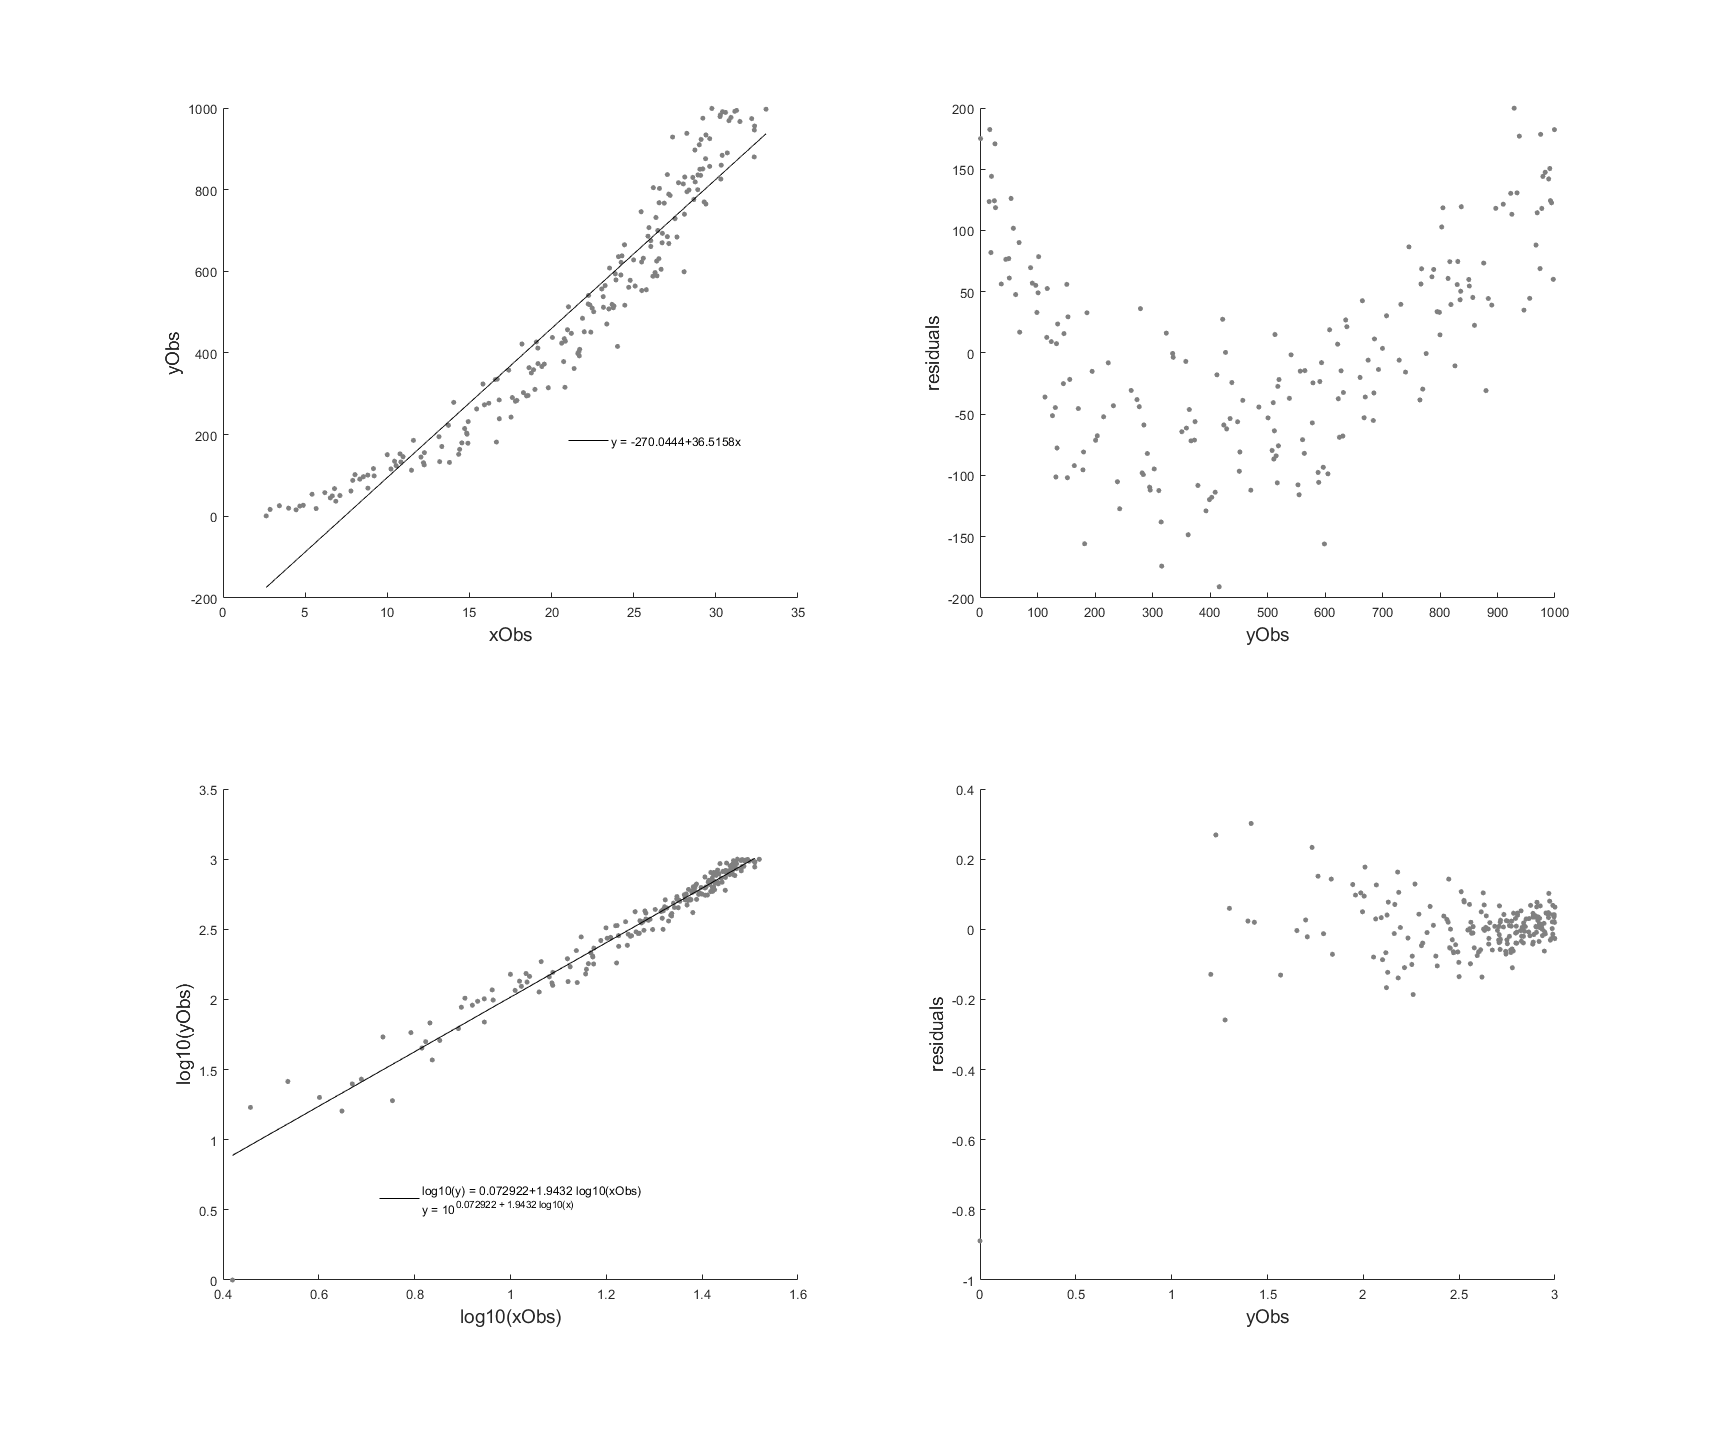

run('log10_log10_transform_example.m');

close all;

Finally, let's try it with some real data hosted on gitHub:

The following three commands reset the workspace by clearing all of the variables, closing all open Figures, and clearing the command line.

clear all; close all; clc;

Define the working folder that you are using

folderIn = 'C:\Users\Matt\OneDrive - Newcastle University\Teaching\2021 - 22\GEO8026\Lecture 4\';

Download example data from gitHub and save it within folderIn as example1.xlsx

websave([folderIn 'regress_example_data1.xlsx'] , 'https://github.com/CatchmentSci/GEO8026_21_22/blob/main/Practical%204/data/regress_example_data1.xlsx?raw=true'); % Download data

Read the data into MATLAB. Note that two seperate lists of characters can be joined into one through the use of square brackets:  

C = readtable([folderIn 'regress_example_data1.xlsx']); 

The data that we have just loaded is a` 325x2 `array consisting of independent data `(:,1)`, and response/dependant variable `(:,2)`. Let's extract this data into two seperate variables:

xIn = C{:,1}; % Extract the first column
yIn = C{:,2}; % Extract the second column

Let's perform an analysis on this data:

xIn = C{:,1}; % Extract the first column
yIn = C{:,2}; % Extract the second column

% Method one
[xData,yData]       = prepareCurveData(xIn,yIn);
t_out               = length(xData);
xData(1:t_out,2)    = 1; % Prep the data for regression
[b,~,r,~,stats]     = regress(yData,xData); % Run the regression
Original_r2         = stats(1,1); % Pull out the R2 value
Original_p          = stats(1,3); % Pull out the p value


%Let's plot the results:
ax1       = subplot(2,2,1); hold on;
set(gcf,'units','normalized','outerposition',[0 0 0.5 1]); 
h(1)      = scatter(xData(:,1),yData,... % we need to specify only the first column due to the column of ones
    'MarkerEdgeColor', [0.5,0.5,0.5],...
    'MarkerFaceColor', [0.5,0.5,0.5],...
    'SizeData', 10);

intervals       = min(xData):0.01:max(xData);  % we need to specify the range of values to calculate the fit for.
h(2)            = plot(intervals,b(2) + b(1).*intervals,'k-'); % Plot the best-fit: b1 = slope, b2 = intecept

ylabel('yObs','FontSize', 14);
xlabel('xObs','FontSize',14);
h_leg(1) = legend(h(2), ['y = ' num2str(b(2)) '+' num2str(b(1)) 'x']);
legend boxoff ;
set(h_leg(1),'Location','best');


% Let's examine the residuals
% The residual vs. fit plot can be used to detect non-linearity and/or unequal variance.
ax2     = subplot(2,2,2); hold on
h(3)    = scatter(yData,r,... % plot the fit vs residuals
    'MarkerEdgeColor', [0.5,0.5,0.5],...
    'MarkerFaceColor', [0.5,0.5,0.5],...
    'SizeData', 10);
xlabel('yObs','FontSize', 14);
ylabel('residuals','FontSize', 14);



What we can observe from the above is that when we run a linear regression on the `xData` and `yData`, a strong ($R^{2}$ = 0.89) and statistically significant (P < 0.01). This indicates there is a strong response in the `yData` from changes in `xData`. As the p value is close to zero we can reject the null hypothesis that $\beta_1 = 0$. However, we should investigate further and check the residuals to try and detect non-linearity and/or unequal variance. When we look at the residuals plot we can see that the variance in the residuals is not equal across the range of `xData`. This is termed heteroskedasticity and can lead to the estimation of less precise model coefficients. A common cause of this is that we have selected an an inappropriate model e.g. not included terms. We should therefore consider whether linear regression on the raw variables is the best course of action? One option is that we transform one or more of the variables . We can choose to transform the `xData`, `yData`, or both. Commonly, we would start with the `xData`. In this instance, performing a log transform on the x-axis data works well:

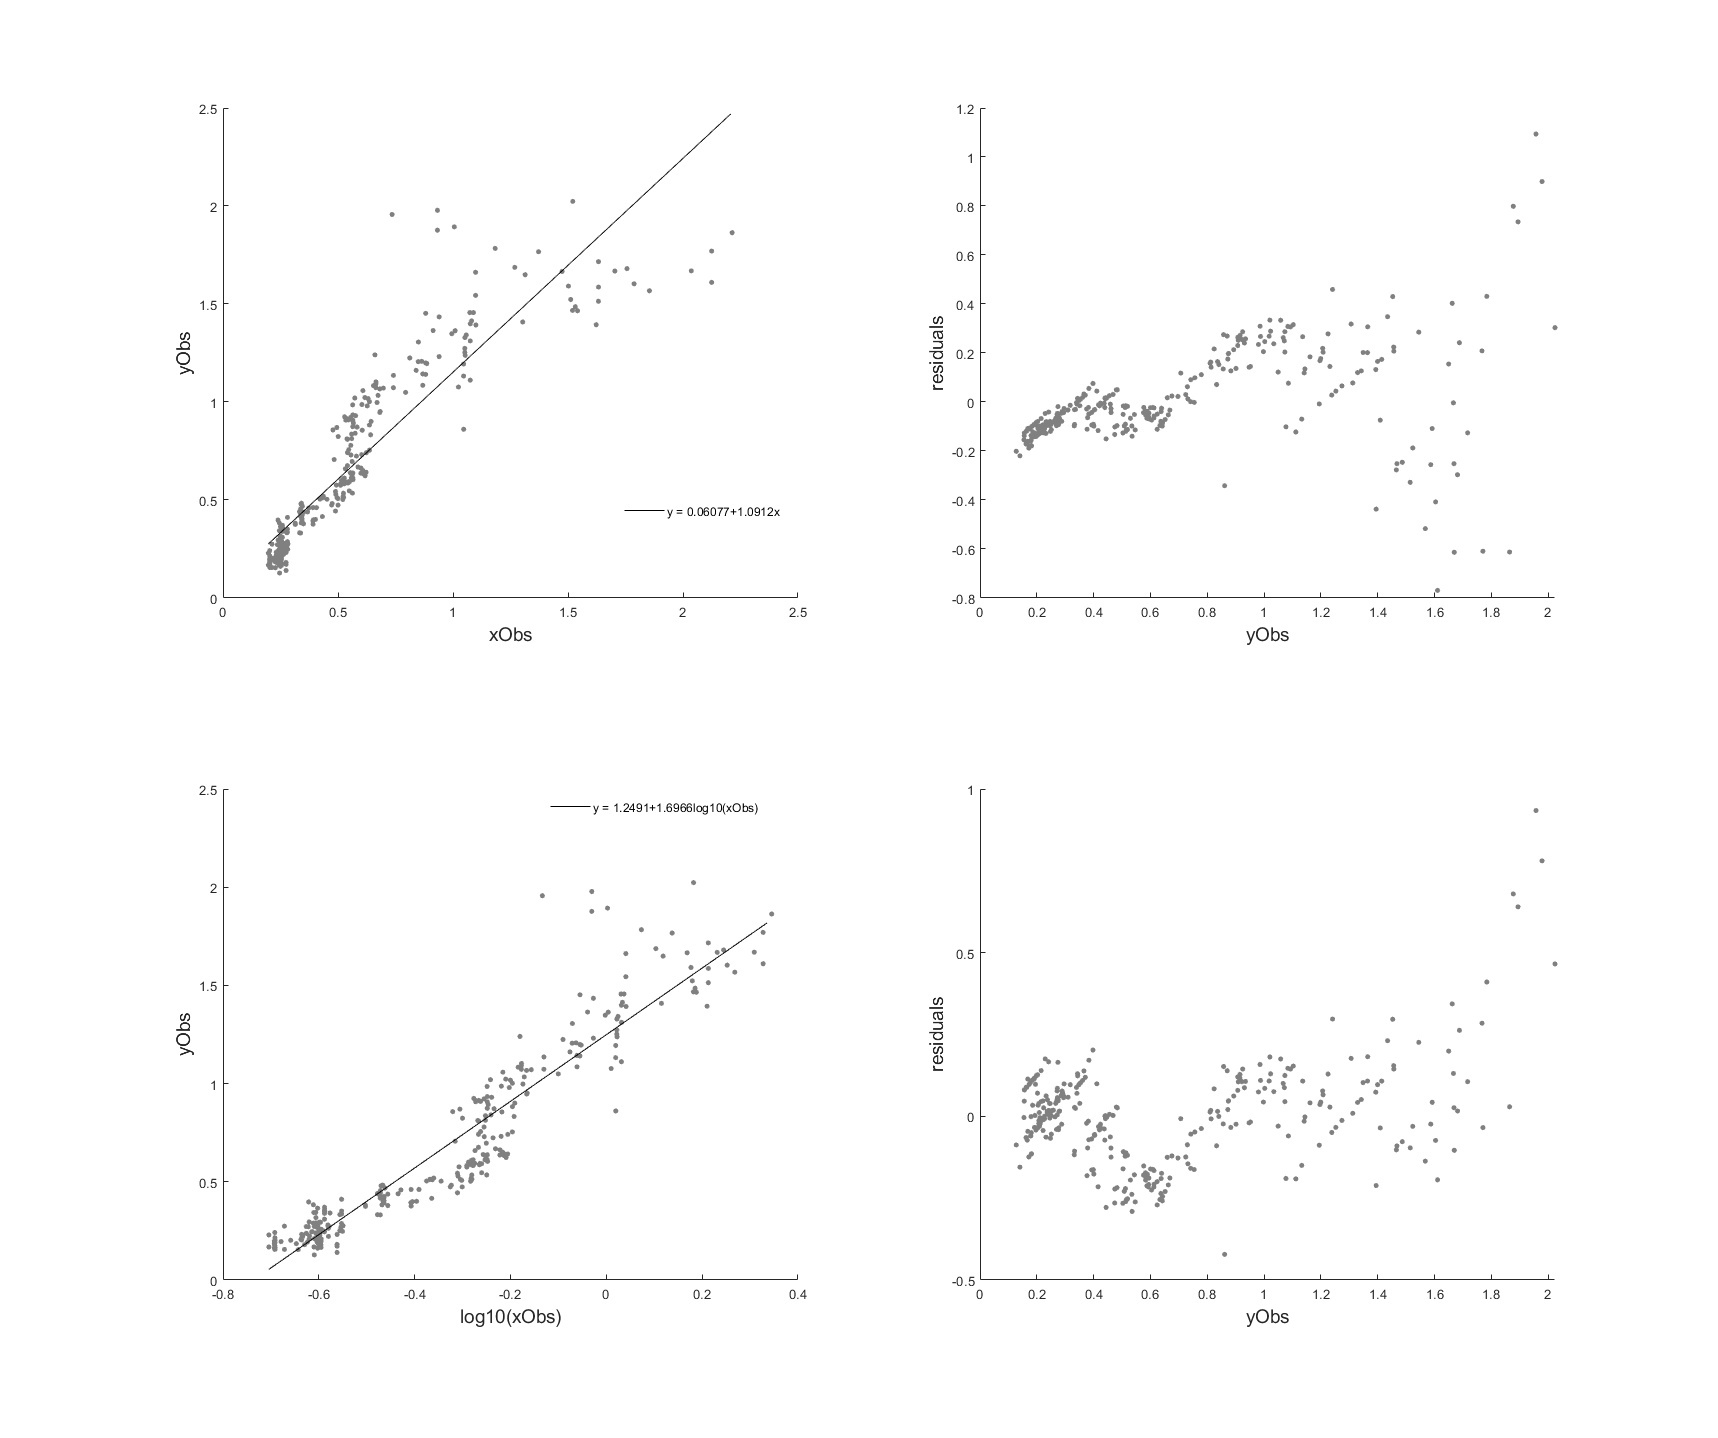


XData_mod               = log10(xData(:,1)); % here we transform the xObs by taking the log of x
t_out                   = length(XData_mod);
XData_mod(1:t_out,2)    = 1; % Prep the data for regression with a column of ones
[b,~,r,~,stats]         = regress(yData,XData_mod); % Run the regression and pull out the coefficients, residuals, stats
Original_r2             = stats(1,1); % Pull out the R2 value
Original_p              = stats(1,3); % Pull out the p value

%Let's plot the results:
ax3     = subplot(2,2,3); hold on
h(4)    = scatter(XData_mod(:,1),yData,... % we need to specify only the column due to the column of ones
    'MarkerEdgeColor', [0.5,0.5,0.5],...
    'MarkerFaceColor', [0.5,0.5,0.5],...
    'SizeData', 10);

intervals   = min(XData_mod):0.01:max(XData_mod);  % we need to specify the range of values to calculate the fit for.
h(5)        = plot(intervals,b(2) + b(1).*intervals,'k-'); % Plot the best-fit: b1 = slope, b2 = intecept
ylabel('yObs','FontSize', 14);
xlabel('log10(xObs)','FontSize', 14);

h_leg(2) = legend(h(5), ['y = ' num2str(b(2)) '+' num2str(b(1)) 'log10(xObs)']);
legend boxoff ;
set(h_leg(2),'Location','best');

% Let's examine the residuals
% The residual vs. fit plot can be used to detect non-linearity and/or unequal variance.
ax4     = subplot(2,2,4); hold on
h(6)    = scatter(yData,r,... % plot the fit vs residuals
    'MarkerEdgeColor', [0.5,0.5,0.5],...
    'MarkerFaceColor', [0.5,0.5,0.5],...
    'SizeData', 10);
xlabel('yObs','FontSize', 14);
ylabel('residuals','FontSize', 14);

We can now see that the variance has become more equal through the incorporation of this transformation (log of `xData`). Furthermore, the $R^{2}$ has increased from 0.83 to 0.89 indicating that a higher explained variance. Whilst we have applied linear regression to the technique, the resultant fit is now no longer linear due to the trasformation. Instead, this is a linear-log fit.

## Part D: Uncertainty 

Now that we have a model which is capable of describing the relationship between `xObs` and `yObs`, we need to consider the uncertainty associated with these estimates. Each coefficient will have uncertainty attached to it. If we assume that the errors are normally distributed, we can extract the uncertainty from the `regress` command (see variable `bint`). However, our errors may not be normally disctibuted in which case these estimates of uncertainty may be inaccurate. In order to remove this bias, we can employ an approach known as `bootstrapping`. It effectively samples the data many times to obtain a better estimate of the regression coefficients. This can be acheived by resampling the cases (Approach 1), or resampling the residuals (Approach 2). Resampling the cases makes no assumption that the model that we have defined is correct. It resamples the data `n` times and produces a new best fit for each random selection of measurements. Conversely, resampling the residuals assumes that the model that has been produced is correct. It then randomly samples the residuals from across the measurements, adds these to the prediction and computes a new best fit. Because resampling the residuals assumes that the developed model is correct, the `ci` associated with this tends to be smaller than when they are extracted using the resampling of the cases.


x           = XData_mod;
y           = yData;
intervals   = min(x):0.01:max(x);  % we need to specify the range of values to calculate the fit for.


% Approach 1: Resample the cases
p_boot             = bootstrp(2000,'polyfit',x(:,1),y,1); % Bootstrap the data 2000 times
p_boot_slope       = p_boot(50:1949,1); % Remove the upper and lower 2.5% of the slopes i.e. use 95%
p_boot_intercept   = p_boot(50:1949,2); % Remove the upper and lower 2.5% of the intercepts i.e. use 95%

% Plot the data
figure(); hold on;
ax5     = subplot(2,1,1); hold on
for a = 1:length(p_boot_slope)
    plot(intervals,p_boot_intercept(a,1) + p_boot_slope(a,1).*intervals,'r-'); hold on;
end

h(7)    = scatter(x(:,1),y,... % we need to specify only the column due to the column of ones
    'MarkerEdgeColor', [0.5,0.5,0.5],...
    'MarkerFaceColor', [0.5,0.5,0.5],...
    'SizeData', 10); hold on;

ylabel('yObs','FontSize', 14);
xlabel('log10(xObs)','FontSize', 14);


% Approach 2: Resample the model residuals
[b,bint,r,~,stats]  = regress(y,x);
yfit                = x*b; % predictions
resid               = y - yfit;

ci = bootci(2000,{@(bootr)regress(yfit+bootr,x),resid}, ...
    'Type','normal');

ax6     = subplot(2,1,2); hold on
h(7)    = scatter(XData_mod(:,1),yData,... % we need to specify only the column due to the column of ones
    'MarkerEdgeColor', [0.5,0.5,0.5],...
    'MarkerFaceColor', [0.5,0.5,0.5],...
    'SizeData', 10); hold on;

intervals   = min(XData_mod):0.01:max(XData_mod);  % we need to specify the range of values to calculate the fit for.
h(8)        = plot(intervals,ci(1,2) + ci(1,1).*intervals,'r-'); % Plot the best-fit: b1 = slope, b2 = intecept
h(9)        = plot(intervals,ci(2,2) + ci(2,1).*intervals,'r-'); % Plot the best-fit: b1 = slope, b2 = intecept

ylabel('yObs','FontSize', 14);
xlabel('log10(xObs)','FontSize', 14);



## Tasks for tomorrow's session:

- Explore your datasets, begining to produce functional relationships between variables.

- Consider extending the regression by using multiple regression when required.